% Lab 1: Rollercoaster 
%
% Objectives: 
%
% -Design a rollercoaster with a loop, 0G parabola,
%  banked turn, braking section, and smooth transitions between all.
% -Determine G-Forces acting throughout rollercoaster.
% -Plot velocity along length of coaster.
%
% Assumptions:
% 
% -Treat rollercoaster cart as a point mass.
% -Neglect drag (always) and friction (except in braking section)
% -Initial velocity is zero
%
% Constraints:
%
% -Max track length: 1250m
% -Upwards G's < 6
% -Downwards G's < 1
% -Forwards G's < 5
% -Backwards G's < 4
% -Lateral G's < 3
%------------------------------------------------------------------------------


% House Cleaning
clc
close all


% Initial Conditions
h0 = 125; % [m]
x0 = 0; % [m]
y0 = 100; % [m]
g = 9.81; % [m/s^2]


%% Roller Coaster
% Ramp
[h1,x1,y1,vel1,G1] = ramp(h0,x0,y0,40,50,g);

% Transition Out of Ramp, Into Loop (Curve)
[h2,x2,y2,vel2,G2,arc_length_trans1] = transition_down_curve(h0,h1(end),x1(end),y1(end),40,40,g);

% Loop
[h3,x3,y3,vel3,G3,arc_length_loop] = loop(h0,h2(end),x2(end),y2(end),17,g);

% Transition Out Of Loop, Into Banked Turn (Straight Line)
[h4,x4,y4,vel4,G4] = transition_line(h0,h3(end),x3(end),y3(end),50,g);

% Banked Turn
[h5,x5,y5,vel5,lat_G5,vert_G5,arc_length_banked] = banked_turn(h0,h4(end),x4(end),y4(end),45,25,g);

% Loop
[h6,x6,y6,vel6,G6,arc_length_loop2] = loop(h0,h5(end),x5(end),y5(end),17,g);

% Transition Out of Loop, Into Curve Transition (Straight Line)
[h7,x7,y7,vel7,G7] = transition_line_reverse(h0,h6(end),x6(end),y6(end),20,g);

% Transition Out of Straight Line Into Parabolic Hill (Curve)
[h8,x8,y8,vel8,G8,arc_length_trans2] = transition_up_curve_reverse(h0,h7(end),x7(end),y7(end),20,40,g);

% Parabolic Hill
[h9,x9,y9,velz9,velx9,G9,arc_length_parabola] = parabola(h8(end),x8(end),y8(end),vel8(end),0,20,g);

vel9 = sqrt(velx9^2 + velz9.^2);

% Ramp Out of Parabolic Hill
[h10,x10,y10,vel10,G10] = ramp_reverse(h0,h9(end),x9(end),y9(end),20,150,g);

% Transition to Ground
[h11,x11,y11,vel11,G11,arc_length_trans3] = transition_down_curve_reverse(h0,h10(end),x10(end),y10(end),30,40,g);

% Braking
[h12,x12,y12,vel12,vert_G12,back_G12,brake_length] = braking(h0,h11(end),x11(end),y11(end),g);

% Verify Total Track Length is Within Range
Track_Length = 50 + arc_length_trans1 + arc_length_loop + 50 + arc_length_banked...
    + arc_length_loop2 + 30 + arc_length_trans2  + arc_length_parabola + 50 + arc_length_trans3 + brake_length(1)

Track_Length = 634.5397



%% Put Together Plotting Vectors
% Positions
x_pos = [x1,x2,x3,x4,x5,x6,x7,x8,x9,x10,x11,x12];
y_pos = [y1,y2,y3,y4,y5,y6,y7,y8,y9,y10,y11,y12];
h_pos = [h1,h2,h3,h4,h5,h6,h7,h8,h9,h10,h11,h12];

% Velocities
vel_whole_track = [vel1,vel2,vel3,vel4,vel5,vel6,vel7,vel8,vel9,vel10,vel11,vel12];


ans = 43.3619

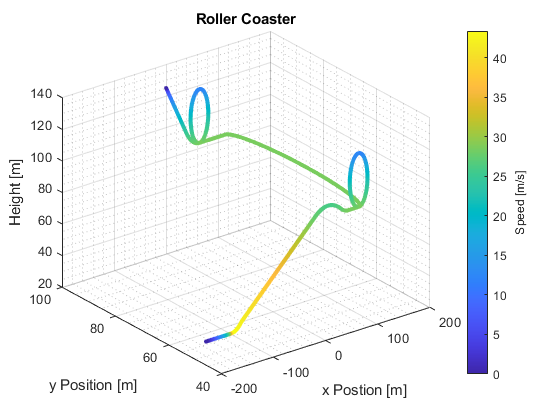

% G's Experienced
G_whole_vert = [G1,G2,G3,G4,vert_G5,G6,G7,G8,G9,G10,G11,vert_G12];

G_whole_lat = [zeros(1,length(G1)),zeros(1,length(G2)),zeros(1,length(G3)),zeros(1,length(G4))...
    ,lat_G5,zeros(1,length(G6)),zeros(1,length(G7)),zeros(1,length(G8)),zeros(1,length(G9)),zeros(1,length(G10))...
    ,zeros(1,length(G11)),zeros(1,length(back_G12))];

G_whole_back = [zeros(1,length(G1)),zeros(1,length(G2)),zeros(1,length(G3)),zeros(1,length(G4))...
    ,zeros(1,length(lat_G5)),zeros(1,length(G6)),zeros(1,length(G7)),zeros(1,length(G8)),zeros(1,length(G9))...
    ,zeros(1,length(G10)),zeros(1,length(G11)),back_G12];


%% Plot Rollercoaster
% Velocity
figure(1);
scatter3(x_pos,y_pos,h_pos,10,vel_whole_track,'filled')
hold on
grid on; grid minor
title('Roller Coaster')
c = colorbar;
c.Label.String = 'Speed [m/s]';
xlabel('x Position [m]')
ylabel('y Position [m]')
zlabel('Height [m]')
hold off

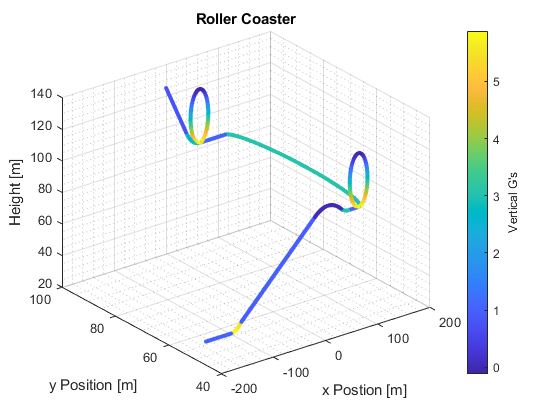


% Vertical G's
figure(2);
scatter3(x_pos,y_pos,h_pos,10,G_whole_vert,'filled')
hold on
grid on; grid minor
title('Roller Coaster')
c = colorbar;
c.Label.String = "Vertical G's";
xlabel('x Position [m]')
ylabel('y Position [m]')
zlabel('Height [m]')
hold off

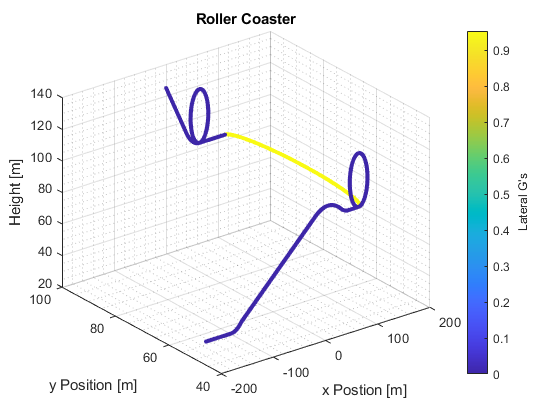


% Lateral G's
figure(3);
scatter3(x_pos,y_pos,h_pos,10,G_whole_lat,'filled')
hold on
grid on; grid minor
title('Roller Coaster')
c = colorbar;
c.Label.String = "Lateral G's";
xlabel('x Position [m]')
ylabel('y Position [m]')
zlabel('Height [m]')
hold off

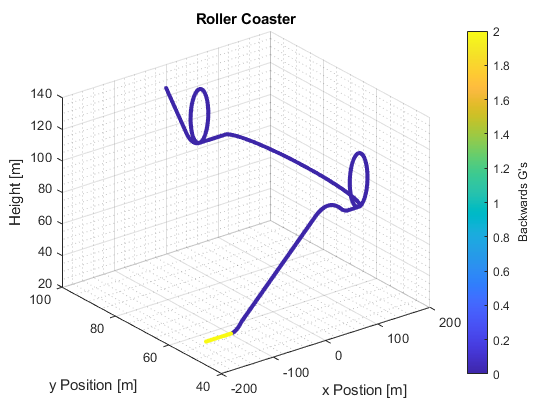


% Backward G's
figure(4);
scatter3(x_pos,y_pos,h_pos,10,G_whole_back,'filled')
hold on
grid on; grid minor
title('Roller Coaster')
c = colorbar;
c.Label.String = "Backwards G's";
xlabel('x Position [m]')
ylabel('y Position [m]')
zlabel('Height [m]')
hold off

function[h_current,x_current,y_current,vel,G_ramp] = ramp(h0,x,y,ramp_theta,ramp_length,g)

% Parameters
ramp_pos = (0:0.1:ramp_length);

% Current Positions
h_current = h0 - ramp_pos * sind(ramp_theta);
x_current = x + ramp_pos * cosd(ramp_theta);
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(ramp_theta);

% G's Experienced
G_ramp = zeros(1,length(x_current));
G_ramp = G_ramp + N ./ g;

end

function[h_current,x_current,y_current,vel,G_ramp2] = ramp_reverse(h0,h,x,y,ramp_theta2,ramp_length2,g)

% Parameters
ramp_pos = (0:0.1:ramp_length2);

% Current Positions
h_current = h - ramp_pos * sind(ramp_theta2);
x_current = x - ramp_pos * cosd(ramp_theta2);
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(ramp_theta2);

% G's Experienced
G_ramp2 = zeros(1,length(x_current));
G_ramp2 = G_ramp2 + N ./ g;

end


function[h_current,x_current,y_current,vel,G_trans1,arc_length] = transition_down_curve(h0,h,x,y,theta_1,R,g)

% Parameters
theta_range = (360 - theta_1:360);
arc_length = (theta_1 / 360) * 2 * pi * R;

% Current Positions
h_current = h + R * cosd(360 - theta_1) - R * cosd(theta_range);
x_current = x - R * sind(360 - theta_1) + R * sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(theta_range) + (vel.^2 / R);

% G's Experienced 
G_trans1 = N ./ g;

end

function[h_current,x_current,y_current,vel,G_trans1,arc_length] = transition_down_curve_reverse(h0,h,x,y,theta_5,R,g)

% Parameters
theta_range = (theta_5:-1:0);
arc_length = (theta_5 / 360) * 2 * pi * R;

% Current Positions
h_current = h + (R* cosd(theta_5) - R * cosd(theta_range));
x_current = x - R * sind(theta_5) + R * sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(theta_range) + (vel.^2 / R);

% G's Experienced 
G_trans1 = N ./ g;

end


function[h_current,x_current,y_current,vel,G_loop,circumference] = loop(h0,h,x,y,R,g)

% Parameters
circumference = 2 * pi * R; % [m]
theta_range = 0:360; % [^o]

% Current Positions
h_current = h + (R - R*cosd(theta_range));
x_current = x + R*sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Acceleration for Normal Force
a_n = vel.^2/R;

% Normal Force
N = g * cosd(theta_range) + a_n;

% G's Experienced
G_loop = N ./ g;

end

function[h_current,x_current,y_current,vel,G_trans2] = transition_line(h0,h,x,y,track_length,g)

% Parameters
x_range = (0:track_length);

% Current Positions
x_current = x + x_range; 
h_current = h + zeros(1,length(x_current));
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g;

% G's Experienced
G_trans2 = zeros(1,length(x_current));
G_trans2 = G_trans2 + N / g;

end

function[h_current,x_current,y_current,vel,G_trans3] = transition_line_reverse(h0,h,x,y,track_length,g)

% Parameters
x_range = (0:track_length);

% Current Positions
x_current = x - x_range; 
h_current = h + zeros(1,length(x_current));
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g;

% G's Experienced
G_trans3 = zeros(1,length(x_current));
G_trans3 = G_trans3 + N / g;

end

function[h_current,x_current,y_current,vel,G_banked_lat,G_banked_vert,arc_length] = banked_turn(h0,h,x,y,bank_theta,R,g)

% Parameters
theta_range = (0:180);
arc_length = (180 / 360) * 2 * pi * R;

% Current Positions
x_current = x + R * sind(theta_range);
y_current = y - R + R * cosd(theta_range);
h_current = h + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Acceleration for Normal Force
a_n = vel.^2/R;

% Normal Force
N_vertical = g * cosd(bank_theta) + a_n * sind(bank_theta);
N_lateral = -sind(bank_theta) * (g - (a_n * cosd(bank_theta)));
 
% G's Experienced
G_banked_lat = zeros(1,length(x_current));
G_banked_vert = zeros(1,length(x_current));
G_banked_lat = G_banked_lat + N_lateral ./ g;
G_banked_vert = G_banked_vert + N_vertical ./ g;

end

function[h_current,x_current,y_current,vel,G_trans4,arc_length] = transition_up_curve_reverse(h0,h,x,y,theta_4,R,g)

% Parameters
theta_range = (0:theta_4);
arc_length = (theta_4 / 360) * 2 * pi * R;

% Current Positions
h_current = h + (R - R * cosd(theta_range));
x_current = x - R * sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(theta_range) + (vel.^2 / R);

% G's Experienced 
G_trans4 = N ./ g;

end

function[h_current,x_current,y_current,vz,vx0,G_parabola,arc_length_parabola] = parabola(h,x,y,vel,~,theta,g)

% Parameters
vx0 = vel * cosd(theta);
vz0 = vel * sind(theta);

% Current Positions and Z Velocity Equations
vz1 = @(t) vel * sind(theta) - (g * t);
x1 = @(t) x + -vx0 * t;
y1 = @(t) y + (0 * t);
h1 =  @(t) -0.5 * g * t.^2 + (vz0) * t + h;

% Define Time Vector
t = (0:0.01:10);

% Generate Vectors WRT Time
x_current = x1(t);
y_current = y1(t);
h_current = h1(t);
vz = vz1(t);

% Find Where Track Returns to Initial Height
stop = find(h_current < h);
stop = stop(1);
t_stop = t(stop);

% Cut Off Vectors At That Point
x_current = x_current(1:stop);
y_current = y_current(1:stop);
h_current = h_current(1:stop);
vz = vz(1:stop);

% Arc Length
f = @(t) sqrt((vel * sind(theta) - (g * t)).^2 + vx0^2 + 1);
arc_length_parabola = integral(f,0,t_stop);

% G's Experienced ... NOTE: Using Kinematic Equations to Generate Parabola
% Makes Our Coaster in "Free Fall"
G_parabola = zeros(1,stop);

end

function[h_end,x_end,y_end,vel_end,G_brake_vert,G_brake_back,track_length] = braking(h0,h,x,y,g)

% Velocity
vel_end = (sqrt(2*g*(h0-h)):-0.1:0);

% Fix Backwards G's
G_brake_back = 2 + zeros(1,length(vel_end));
G_brake_vert = 1 + zeros(1,length(vel_end));

% Track Length
track_length = vel_end.^2./(2*g*G_brake_back);

% Ending Positions
x_end = flip(-track_length + x);
h_end = h + zeros(1,length(x_end));
y_end = y + zeros(1,length(x_end));
vel_end = vel_end + zeros(1,length(x_end));

end